clear;

# kp2TB test

### useful tool

s_0   = pauli_matric(0)  ;  s_x = pauli_matric(1);  s_y =  pauli_matric(2) ;  s_z = pauli_matric(3);
sigma_0 = pauli_matric(0);sigma_x =  pauli_matric(1);sigma_y =  pauli_matric(2);sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0);  tau_x =  pauli_matric(1);  tau_y =  pauli_matric(2);  tau_z = pauli_matric(3);

syms C0 C1 C2 real;
syms M0 M1 M2 real;
syms A0 B real;
syms k_x k_y k_z real;

### Model

M       = -M0+M2*(k_x^2+k_y^2)+M1*(k_z^2);
E0k     = C0+C2*(k_x^2+k_y^2)+C1*(k_z^2);
A       = A0;
k_plus  = k_x + 1i* k_y;
k_minus = k_x - 1i* k_y;
%
BHZ = HK(4,2);
% 4: orbital number  dimension of mat
% 3: To k^3
%
BHZ = BHZ ...
    +Term(A*k_x ,sigma_z*tau_x )...
    +Term(A*k_y ,sigma_0*tau_y )...
    +Term(E0k   ,sigma_0*tau_0 )...
    +Term(M     ,sigma_0*tau_z )...
    +Term(B*(k_x^2-k_y^2),sigma_x*tau_x )...
    +Term(2*B*(k_x*k_y),sigma_y*tau_x )...
    ;

Setting 1/1 term into HK ...


Setting 1/1 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 2/2 term into HK ...


Setting 1/1 term into HK ...


% BHZ = BHZ.Subsall('sym');

#### 展示 HK

sym(BHZ)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & -A_{0}\,k_{y}\,\mathrm{i}+A_{0}\,k_{x} & 0 & \sigma_{3}\\ A_{0}\,k_{y}\,\mathrm{i}+A_{0}\,k_{x} & \sigma_{2} & \sigma_{3} & 0\\ 0 & \sigma_{4} & \sigma_{1} & -A_{0}\,k_{y}\,\mathrm{i}-A_{0}\,k_{x}\\ \sigma_{4} & 0 & A_{0}\,k_{y}\,\mathrm{i}-A_{0}\,k_{x} & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=C_{0}-M_{0}+{k_{x}}^{2}\,\left(M_{2}+C_{2}\right)+{k_{y}}^{2}\,\left(M_{2}+C_{2}\right)+{k_{z}}^{2}\,\left(M_{1}+C_{1}\right)\\ \sigma_{2}=C_{0}+M_{0}+{k_{x}}^{2}\,\left(-M_{2}+C_{2}\right)+{k_{y}}^{2}\,\left(-M_{2}+C_{2}\right)+{k_{z}}^{2}\,\left(-M_{1}+C_{1}\right)\\ \sigma_{3}=-B\,{k_{y}}^{2}-2\,B\,k_{x}\,k_{y}\,\mathrm{i}+B\,{k_{x}}^{2}\\ \sigma_{4}=-B\,{k_{y}}^{2}+2\,B\,k_{x}\,k_{y}\,\mathrm{i}+B\,{k_{x}}^{2} \end{array}$$

### PARA

% unit eV 
M0     = -1   ;
%M0     = -0.25   ;
% unit eV Ang
A0      =  1      ;
%B      =  4.1      ;
% unit eV Ang^2
C0     =  0     ; 
C1     =  0     ;
C2     =  0     ;
M1     =  -0.5      ;
M2     =  -0.5  ;
B     =   1   ;
% unit    Ang ! must include this variable: a b c!
a      =  1        ;
b      =  1       ;
c      =  1        ;
BHZ = BHZ <'POSCAR_6';

### kp2TB

BHZ_TB= BHZ.kp2TB();

#### 展示 HR

BHZ_TB.list('vpa',false);

# R1 R2 R3 i j real imag


### HR2Htrig

% indirect
% BHZ_TB_L  =  BHZ_TB.rewrite();
% BHZ_Htrig = BHZ_TB_L.HR2Htrig();
% direct
BHZ_Htrig = BHZ_TB.HR2Htrig();

please check whether the Rm and orbL is properly set.


$$\left(\begin{array}{ccc} 1 & 0 & 0\\ -\frac{1}{2} & \frac{\sqrt{3}}{2} & 0\\ 0 & 0 & \frac{\sqrt{3}}{2} \end{array}\right)$$

$$\left(\begin{array}{ccc} \frac{1}{2} & \frac{1}{2} & \frac{1}{2}\\ \frac{1}{2} & \frac{1}{2} & \frac{1}{2}\\ \frac{1}{2} & \frac{1}{2} & \frac{1}{2}\\ \frac{1}{2} & \frac{1}{2} & \frac{1}{2} \end{array}\right)$$

Transforming 9/9 th H(NRPT) into Htrig obj ...


#### 展示 Htrig

sym(BHZ_Htrig)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{3} & \sigma_{2}+\sigma_{7}+\sigma_{1} & 0 & \sigma_{6}\\ \sigma_{2}+\sigma_{7}-\sigma_{1} & \sigma_{4} & \sigma_{6} & 0\\ 0 & \sigma_{5} & \sigma_{3} & -\sigma_{2}-\sigma_{7}+\sigma_{1}\\ \sigma_{5} & 0 & -\sigma_{2}-\sigma_{7}-\sigma_{1} & \sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\sqrt{3}\,A_{0}\,\cos\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}}{3}\\ \sigma_{2}=\frac{2\,A_{0}\,\sin\left(k_{x}\right)}{3}\\ \sigma_{3}=C_{0}+\frac{8\,C_{1}}{3}+4\,C_{2}-M_{0}+\frac{8\,M_{1}}{3}+4\,M_{2}-\cos\left(\frac{\sqrt{3}\,k_{z}}{2}\right)\,\left(\frac{8\,M_{1}}{3}+\frac{8\,C_{1}}{3}\right)-\cos\left(k_{x}\right)\,\left(\frac{4\,M_{2}}{3}+\frac{4\,C_{2}}{3}\right)-\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{8}\,\left(\frac{8\,M_{2}}{3}+\frac{8\,C_{2}}{3}\right)\\ \sigma_{4}=C_{0}+\frac{8\,C_{1}}{3}+4\,C_{2}+M_{0}-\frac{8\,M_{1}}{3}-4\,M_{2}-\cos\left(\frac{\sqrt{3}\,k_{z}}{2}\right)\,\left(-\frac{8\,M_{1}}{3}+\frac{8\,C_{1}}{3}\right)-\cos\left(k_{x}\right)\,\left(-\frac{4\,M_{2}}{3}+\frac{4\,C_{2}}{3}\right)-\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{8}\,\left(-\frac{8\,M_{2}}{3}+\frac{8\,C_{2}}{3}\right)\\ \sigma_{5}=\frac{8\,B\,\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{8}}{3}-\frac{4\,B\,\cos\left(k_{x}\right)}{3}-\frac{4\,B}{3}-\frac{8\,\sqrt{3}\,B\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}}{3}\\ \sigma_{6}=\frac{8\,B\,\cos\left(\frac{k_{x}}{2}\right)\,\sigma_{8}}{3}-\frac{4\,B\,\cos\left(k_{x}\right)}{3}-\frac{4\,B}{3}+\frac{8\,\sqrt{3}\,B\,\sin\left(\frac{k_{x}}{2}\right)\,\sin\left(\frac{\sqrt{3}\,k_{y}}{2}\right)\,\mathrm{i}}{3}\\ \sigma_{7}=\frac{2\,A_{0}\,\sin\left(\frac{k_{x}}{2}\right)\,\sigma_{8}}{3}\\ \sigma_{8}=\cos\left(\frac{\sqrt{3}\,k_{y}}{2}\right) \end{array}$$

### BULK

% bandplot
BHZ_TB_n = BHZ_TB.Subsall();
BHZ_TB_n = BHZ_TB_n <'KPOINTS_6';
EIGENCAR = BHZ_TB_n.EIGENCAR_gen();

BAND caculating 364/364 ...


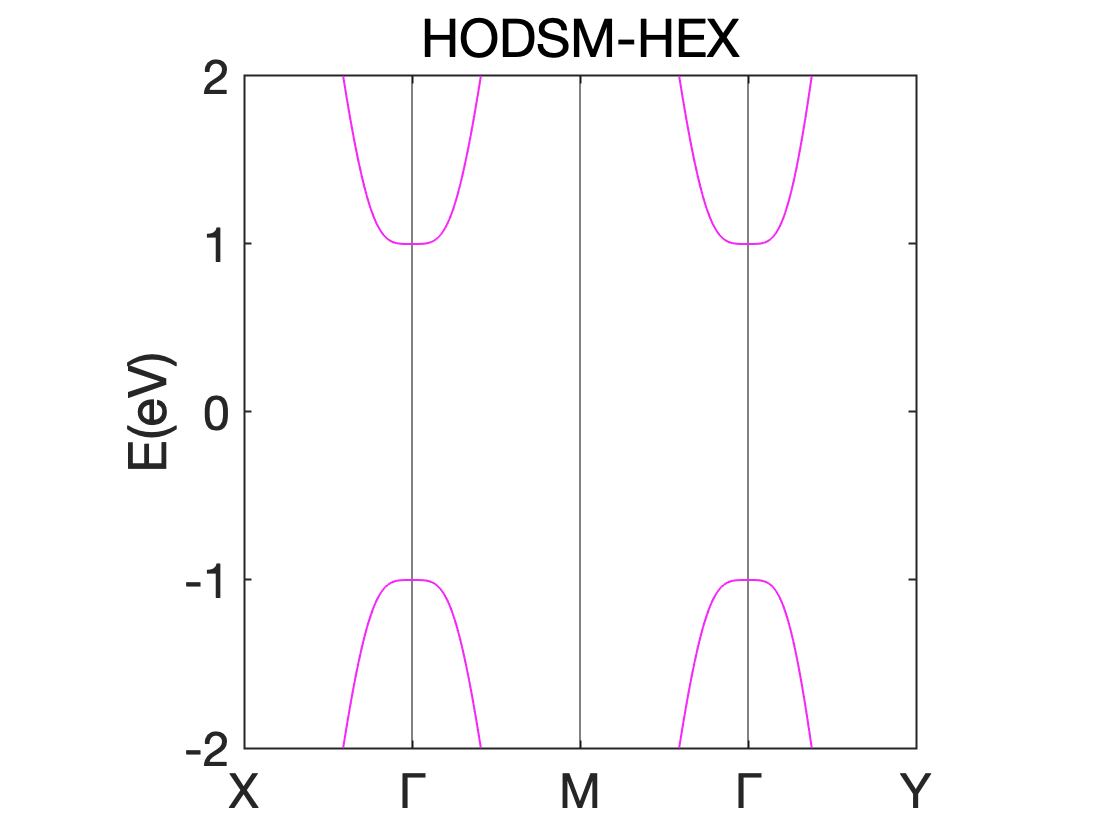

bandplot(EIGENCAR,[-2,2],'title',"HODSM-HEX",'KPOINTS','KPOINTS_6');

### WilsonLoop

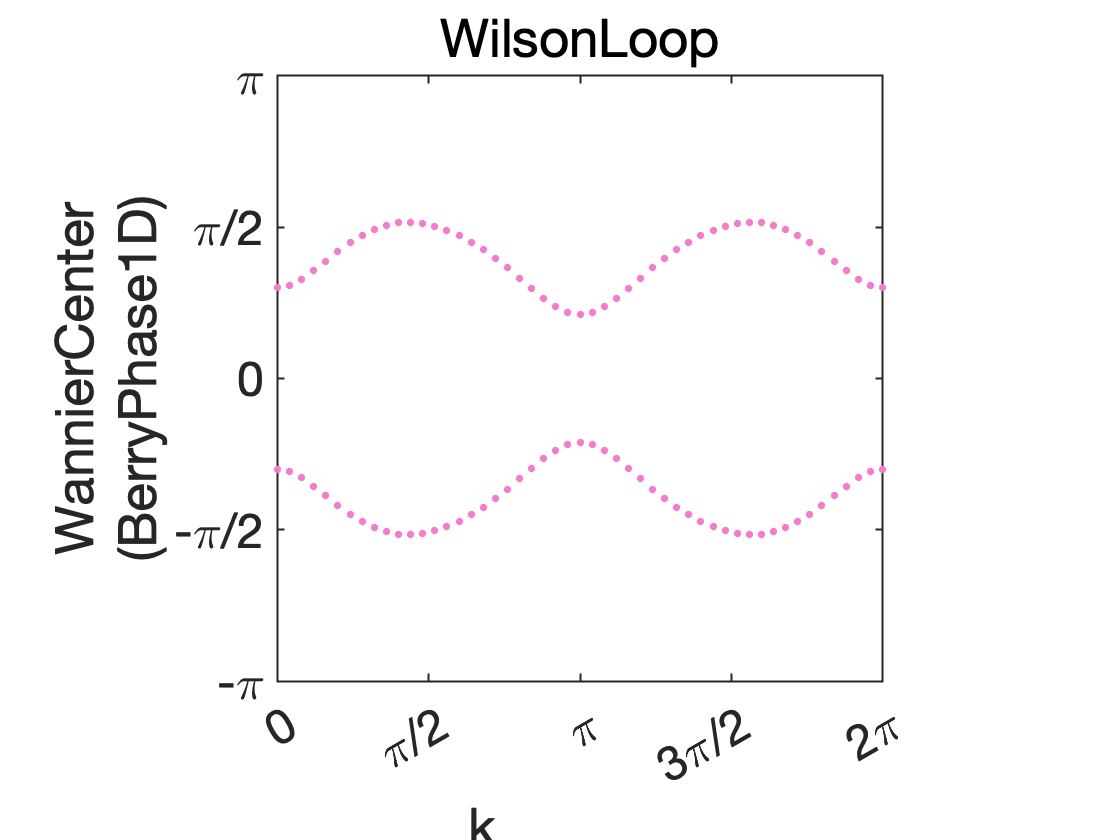

[BFCAR,~,klist_l] = BHZ_TB_n.WilsonLoop();
[fig,ax] = vasplib.WilsonLoopPlot(BFCAR,klist_l);          